# 2: Restricted 3-Body Problem

Working with live script makes it easier to analyze the problem while changing parameters.

## Given Model of The Problem

Second order differential equations:

- y1'' = y1 + 2*y2' - m2*(y1 + m1)/D1 - m1*(y1 - m2)/D2

- y2'' = y2 - 2*y1' - m2*y2/D1 - m1*y2/D2

- D1 = ((y1 + m1)^2 + y2^2)^(3/2)

- D2 = ((y1 - m2)^2 + y2^2)^(3/2)

- y1(0) = 0.994

- y1'(0) = 0

- y2(0) = 0

- y2'(0) = -2.0015851063790825

Transform these second order equations to first order equations:

*Note that: I created y(1), y(2), y(3), y(4) row vectors for new system of first order differential equations.*

- y(1) = y1, y(2) = y1', y(3) = y2, y(4) = y2'

- y(2)' = y(1) + 2*y(4) - m2*(y(1) + m1)/D1 - m1*(y(1) - m2)/D2;

- y(4)' = y(3) - 2*y(2) - m2*y(3)/D1 - m1*y(3)/D2; 

- y(1)' = y(2); 

- y(3)' = y(4); 

- D1 = @(y(1),y(3)) ((y(1) + m1)^2 + y(3)^2)^(3/2);

- D2 = @(y(1),y(3)) ((y(1) - m2)^2 + y(3)^2)^(3/2);

- y(1)(0) = 0.994;

- y(2)(0) = 0;

- y(3)(0) = 0;

- y(4)(0) = -2.0015851063790825;

First order system of differential equations:

Creating a function handle for first order differential equations makes our code neater and more readable.

dy{1} = @(y) y(2);
dy{2} = @(y) y(1) + 2*y(4) - m2*(y(1) + m1)/((y(1) + m1).^2 + y(3).^2)...
    .^(3/2) - m1*(y(1) - m2)/((y(1) - m2).^2 + y(3).^2).^(3/2);
dy{3} = @(y) y(4);
dy{4} = @(y) y(3) - 2*y(2) - m2*y(3)/((y(1) + m1).^2 + y(3).^2).^(3/2)...
    - m1*y(3)/((y(1) - m2).^2 + y(3).^2).^(3/2);

Initial values:

yi(1) = 0.994;
yi(2) = 0;
yi(3) = 0;
yi(4) = -2.0015851063790825;

## Parameters

Masses:

m1 = 0.012277471; % mass of Moon
m2 = 1 - m1; % mass of Earth

Period:

T = 17.06521656015796; % Time required for one full round of orbit

## Values Needed To Apply Numeric Solutions

Step sizes:

h_e = T/24000; % euler
h_rk4 = T/6000; % rk4

Interval:

tmin = 0; % time starts from zero
tmax = T;

## Euler Solution

*Values needed to apply Euler method:*

h = h_e;            % Step Size
t = tmin:h:tmax;    % Interval
n = (tmax-tmin)/h;  % Number of iterations
y =  zeros(4,n);    % Vectors
y(:,1) = yi(:);     % Initial conditions

Apply the Euler method:

for i=1:n
    for j=1:4
        y(j,i+1) = y(j,i) + h*dy{j}(y(:,i));
    end
end

Position vectors from this solution:

y1_e = y(1,:);
y2_e = y(3,:);

Necessary code to plot the results:

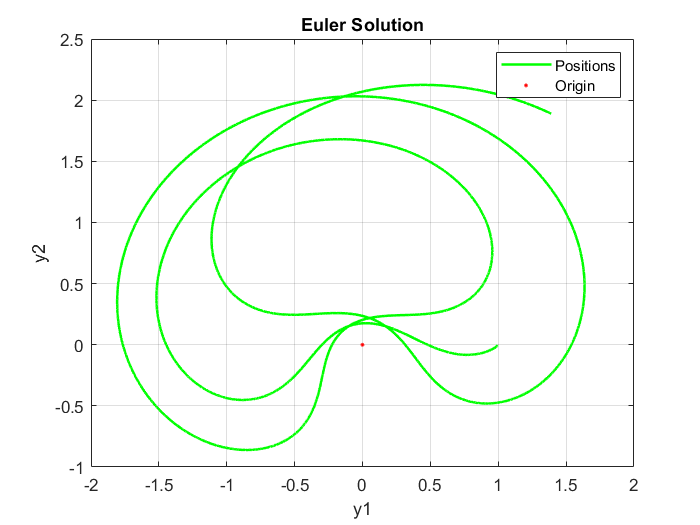

figure
plot(y1_e,y2_e, 'g', 'linewidth', 1.5)
hold on, grid on
plot(0,0, '.r', 'linewidth', 3)
title('Euler Solution')
xlabel('y1')
ylabel('y2')
legend('Positions', 'Origin');

## 4th Order Runge Kutta Solution

*Values needed to apply RK4 method:*

h = h_rk4;          % Step Size
t = tmin:h:tmax;    % Interval
n = (tmax-tmin)/h;  % Number of Iterations
y =  zeros(4,n);    % Vectors
y(:,1) = yi(:);     % Initial Conditions

First, create the function handle to find f values (f1, f2, f3, f4) and the vector matrix to store these f values:

f{1} = @(g,y,h,fv) g(y);
f{2} = @(g,y,h,fv) g(y + h/2*fv);
f{3} = @(g,y,h,fv) g(y + h/2*fv);
f{4} = @(g,y,h,fv) g(y + h*fv);
fv = zeros(4,4); % Each row stores f values for each equation

Apply the RK4 method:

tic
for i=1:n
    for j=1:4 % four f values
        for k=1:4 % four equations
            if j>1
                fv(k,j) = f{j}(dy{k}, y(:,i), h, fv(:,j-1)); % for f2, f3, f4
            else
                fv(k,j) = f{j}(dy{k}, y(:,i), h, fv(:,j)); % for f1
            end
        end
    end
    y(:,i+1) = y(:,i) + h/6*(fv(:,1) + 2*fv(:,2) + 2*fv(:,3) + fv(:,4));
end
elapsedTime_rk4 = toc

elapsedTime_rk4 =    0.410894800000000


Position vectors from this solution:

y1_rk4 = y(1,:);
y2_rk4 = y(3,:);

Necessary code to plot the results:

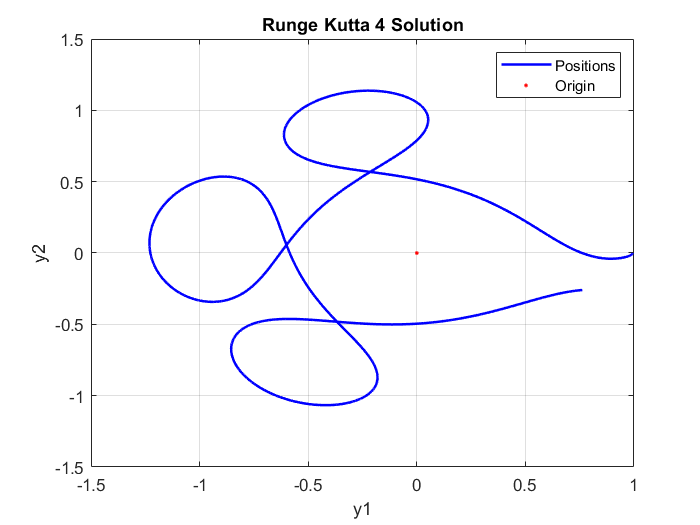

figure
plot(y1_rk4,y2_rk4, 'b', 'linewidth', 1.5)
hold on, grid on
plot(0,0, '.r', 'linewidth', 3)
title('Runge Kutta 4 Solution')
xlabel('y1')
ylabel('y2')
legend('Positions', 'Origin');

## ODE45 Solution

Ode45 takes three parameters; these are odefcn function, tspan and y0. 

tspan is a one by two matrix which stores the minimum and maximum values of the interval:

tspan = [tmin tmax];

y0 is the initial values:

y0 = [yi(1) yi(2) yi(3) yi(4)];

Apply the ode45 function:

tic
[t,y] = ode45(@(t,y) odefcn(y,m1,m2), tspan, y0);
elapsedTime_ode = toc

elapsedTime_ode =    0.011470600000000


Store the values found in this solution (in row vectors):

y1_ode45 = y(:,1);
y2_ode45 = y(:,3);

Necessary code to plot the results:

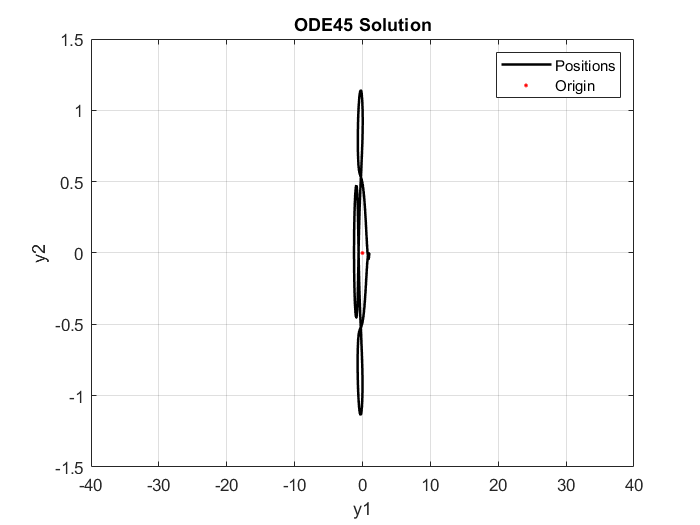

figure
plot(y1_ode45,y2_ode45, 'k', 'linewidth', 1.5)
hold on, grid on
plot(0,0, '.r', 'linewidth', 3)
title('ODE45 Solution')
xlabel('y1')
ylabel('y2')
xlim([-40 40])
legend('Positions', 'Origin');

odecfn is a local function which stores the first order differential equations:

function dydt = odefcn(y,m1,m2)
dydt = zeros(4,1);
dydt(1) = y(2);
dydt(2) = y(1) + 2*y(4) - m2*(y(1) + m1)/((y(1) + m1).^2 + y(3).^2)...
      .^(3/2) - m1*(y(1) - m2)/((y(1) - m2).^2 + y(3).^2).^(3/2);
dydt(3) = y(4);
dydt(4) = y(3) - 2*y(2) - m2*y(3)/((y(1) + m1).^2 + y(3).^2).^(3/2)...
      - m1*y(3)/((y(1) - m2).^2 + y(3).^2).^(3/2);
end
